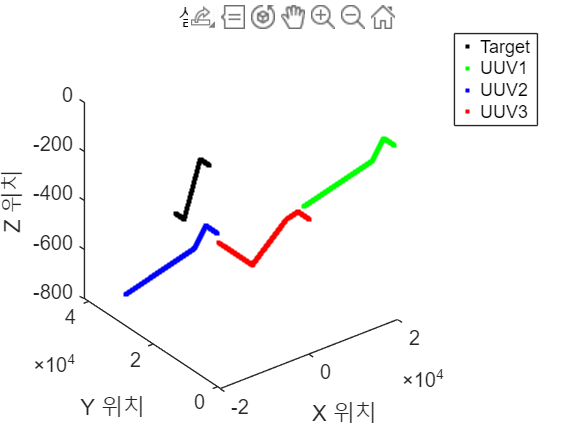

% trajectory 행렬 생성
time = 1000;
True_Target = zeros(time, 6);
True_UUV1 = zeros(time, 6);
True_UUV2 = zeros(time, 6);
True_UUV3 = zeros(time, 6);
DOP = zeros(time, 1);
SimulationSetting=zeros(time, 31);

[True_Target, True_UUV1, True_UUV2, True_UUV3] = Real_trajectory( ...
     90, -2,  90, -2, 90 ,-1, ...%초록 파란 빨강
     90, -1,  90,  -1, 90 ,-1.5, ...
   time,True_Target,True_UUV1,True_UUV2,True_UUV3);
%Target 각도
% 90 -20 40 -25                                                        

%     115, -17,  80, -20, 89 ,-19, ...
%     95, -24,  60, -21, 80 ,-15, ...
%     UUV1 = [10000; 1000; -100; UUV1_vel*cos(UUV1_Eheading1)*cos(UUV1_Aheading1); UUV1_vel*sin(UUV1_Aheading1); UUV1_vel*sin(UUV1_Eheading1)];
%     UUV2 = [-10000; 1000; -100; UUV2_vel*cos(UUV2_Eheading1)*cos(UUV2_Aheading1); UUV2_vel*sin(UUV2_Aheading1); UUV2_vel*sin(UUV2_Eheading1)];
%     UUV3 = [0; 100; -4000; UUV3_vel*cos(UUV3_Eheading1)*cos(UUV3_Aheading1); UUV3_vel*sin(UUV3_Aheading1); UUV3_vel*sin(UUV3_Eheading1)];
%     Target = [0; 10000; -2000; Target_vel*cos(Target_Eheading1)*cos(Target_Aheading1); Target_vel*sin(Target_Aheading1); Target_vel*sin(Target_Eheading1)];

% [Esti_Target_pos] = Esti_EKF(True_Target,True_UUV1,True_UUV2,True_UUV3,CDN,Esti_Target_pos,time);%, Esti_Target_pro
% 
 plot4line(True_Target,True_UUV1,True_UUV2,True_UUV3)

% plot5line(True_Target,True_UUV1,True_UUV2,True_UUV3,Esti_Target_pos)



  for i = 1 : time
      PDOP = calculatedop(True_Target(i,1:3),True_UUV1(i,1:3), True_UUV2(i,1:3), True_UUV3(i,1:3));
      DOP(i,1) = PDOP;
  end



DOPgoodtrajectories1 = struct();

% Adding fields (replace 'Field1', 'Field2' with actual field names)
DOPgoodtrajectories1.target = True_Target(501:end,1:3);
DOPgoodtrajectories1.mship = True_UUV3(501:end,1:3);
DOPgoodtrajectories1.torpedo1 = True_UUV1(501:end,1:3); 
DOPgoodtrajectories1.torpedo2 = True_UUV2(501:end,1:3); 


%궤적 생성 함수
function [True_Target, True_UUV1, True_UUV2, True_UUV3] = Real_trajectory( ...
    UUV1Azimuth1, UUV1Elev1, UUV2Azimuth1, UUV2Elev1,UUV3Azimuth1, UUV3Elev1, ...
    UUV1Azimuth2, UUV1Elev2, UUV2Azimuth2, UUV2Elev2,UUV3Azimuth2, UUV3Elev2, ...
    time, True_Target, True_UUV1, True_UUV2, True_UUV3)

    % 속도와 각도 세팅
    Target_vel = 11.32;%(22노트)
    UUV1_vel = 28.29;%55노트
    UUV2_vel = 28.29;
    UUV3_vel = 28.29;

    % UUV1
    UUV1_Aheading1 = deg2rad(UUV1Azimuth1);
    UUV1_Eheading1 = deg2rad(UUV1Elev1);
    UUV1_Aheading2 = deg2rad(UUV1Azimuth2);
    UUV1_Eheading2 = deg2rad(UUV1Elev2);

    % UUV2
    UUV2_Aheading1 = deg2rad(UUV2Azimuth1);
    UUV2_Eheading1 = deg2rad(UUV2Elev1);
    UUV2_Aheading2 = deg2rad(UUV2Azimuth2);
    UUV2_Eheading2 = deg2rad(UUV2Elev2);

    % UUV3
    UUV3_Aheading1 = deg2rad(UUV3Azimuth1);
    UUV3_Eheading1 = deg2rad(UUV3Elev1);
    UUV3_Aheading2 = deg2rad(UUV3Azimuth2);
    UUV3_Eheading2 = deg2rad(UUV3Elev2);

    % Target
    Target_Aheading1 = deg2rad(90);
    Target_Eheading1 = deg2rad(0);
    Target_Aheading2 = deg2rad(85);
    Target_Eheading2 = deg2rad(-3);

    % 초기 상태 설정
    UUV1 = [20000; 0; -100; UUV1_vel*cos(0)*cos(UUV1_Aheading1); UUV1_vel*sin(UUV1_Aheading1); UUV1_vel*sin(0)];
    UUV2 = [-20000; 0; -175; UUV2_vel*cos(0)*cos(UUV2_Aheading1); UUV2_vel*sin(UUV2_Aheading1); UUV2_vel*sin(0)];
    UUV3 = [0; -1000; -250; UUV3_vel*cos(0)*cos(UUV3_Aheading1); UUV3_vel*sin(UUV3_Aheading1); UUV3_vel*sin(0)];
    Target = [0; 30000; -300; Target_vel*cos(Target_Eheading1)*cos(Target_Aheading1); Target_vel*sin(Target_Aheading1); Target_vel*sin(Target_Eheading1)];

    % 이동 모델
    motion_model = [1 0 0 1 0 0;
                    0 1 0 0 1 0;
                    0 0 1 0 0 1;
                    0 0 0 1 0 0;
                    0 0 0 0 1 0;
                    0 0 0 0 0 1];

    % 시뮬레이션 시작(궤적생성)
    for i = 1 : time
        if i == time/8
            UUV1 = rotate_model(UUV1,UUV1_vel,UUV1_Aheading1,UUV1_Eheading1);
            UUV2 = rotate_model(UUV2,UUV2_vel,UUV2_Aheading1,UUV2_Eheading1);
            UUV3 = rotate_model(UUV3,UUV3_vel,UUV3_Aheading1,UUV3_Eheading1);
        end

        if i == time/4 % 회전각도 변화
            Target = rotate_model(Target,Target_vel,Target_Aheading2,Target_Eheading2);
            UUV1 = rotate_model(UUV1,UUV1_vel,UUV1_Aheading2,UUV1_Eheading2);
            UUV2 = rotate_model(UUV2,UUV2_vel,UUV2_Aheading2,UUV2_Eheading2);
            UUV3 = rotate_model(UUV3,UUV3_vel,UUV3_Aheading2,UUV3_Eheading2);
        end

        if i == time*5/8
            %UUV1 = rotate_model(UUV1,UUV1_vel,deg2rad(60),deg2rad(0));
            %UUV2 = rotate_model(UUV2,UUV2_vel,deg2rad(120),deg2rad(0));
            UUV3 = rotate_model(UUV3,UUV3_vel,UUV3_Aheading2,deg2rad(0));
        end

        if i == time * 3 / 4
            Target = rotate_model(Target,Target_vel,deg2rad(90),deg2rad(0));
        end
        
    Target = nextmotion_model(Target,motion_model);
    UUV1 = nextmotion_model(UUV1,motion_model);
    UUV2 = nextmotion_model(UUV2,motion_model);
    UUV3 = nextmotion_model(UUV3,motion_model);

    True_Target(i, :) = Target;
    True_UUV1(i, :) = UUV1;
    True_UUV2(i, :) = UUV2;
    True_UUV3(i, :) = UUV3;

    end
end

%다음 dt로의 이동
function x = nextmotion_model(x, f)
    x = f * x;
end
%다음 헤딩각도 변경
function x = rotate_model(x, vel, update_heading, update_elevation)
    heading = update_heading;
    elevation = update_elevation;
    x(4) = vel * cos(heading) * cos(elevation); % X 방향 속도
    x(5) = vel * sin(heading) * cos(elevation); % Y 방향 속도
    x(6) = vel * sin(elevation); % Z 방향 속도
end





%DOP 계산
function [DOP] = calculatedop(Target, UUV1, UUV2, UUV3)
    % PDOP를 계산하는 함수

    % UUV의 좌표를 설정합니다.
    x1 = UUV1(1); y1 = UUV1(2); z1 = UUV1(3);
    x2 = UUV2(1); y2 = UUV2(2); z2 = UUV2(3);
    x3 = UUV3(1); y3 = UUV3(2); z3 = UUV3(3);
    
    % 목표(Target)의 좌표를 설정합니다.
    xt = Target(1); yt = Target(2); zt = Target(3);
    
    % UUV와 Target 사이의 거리 계산
    d1 = sqrt((x1 - xt)^2 + (y1 - yt)^2 + (z1 - zt)^2);
    d2 = sqrt((x2 - xt)^2 + (y2 - yt)^2 + (z2 - zt)^2);
    d3 = sqrt((x3 - xt)^2 + (y3 - yt)^2 + (z3 - zt)^2);
    
    % 기울기 행렬(G)을 계산합니다.
    G = [ (x1 - xt) / d1, (y1 - yt) / d1, (z1 - zt) / d1;
          (x2 - xt) / d2, (y2 - yt) / d2, (z2 - zt) / d2;
          (x3 - xt) / d3, (y3 - yt) / d3, (z3 - zt) / d3];
    
    % (G' * G)의 역행렬을 계산하여 Q 행렬을 구합니다.
    Q = inv(G' * G);
    
    % PDOP는 Q 행렬의 대각 원소를 이용하여 계산합니다.
    PDOP = sqrt(Q(1,1) + Q(2,2) + Q(3,3));
    
    % 최종 PDOP 값을 반환합니다.
    DOP = PDOP;
end


%궤적및 그래프 그리는 함수
%Target UUV1 UUV2 실제 궤적 그리기
function UUV5Target = plot5line(Target,UUV1,UUV2,UUV3,Esti_Tar)
    figure;
    plot3(Target(:, 1), Target(:, 2),Target(:,3), 'k.', 'LineWidth', 2); hold on;
    plot3(UUV1(:, 1), UUV1(:, 2),UUV1(:, 3), 'g-', 'LineWidth', 2);
    plot3(UUV2(:, 1), UUV2(:, 2),UUV2(:, 3), 'b-', 'LineWidth', 2);
    plot3(UUV3(:, 1), UUV3(:, 2),UUV3(:, 3), '-y', 'LineWidth', 2);
    plot3(Esti_Tar(:, 1), Esti_Tar(:, 2),Esti_Tar(:, 3), 'r-', 'LineWidth', 1);

    xlabel('X 위치(m)');
    ylabel('Y 위치(m)');
    zlabel('Z 위치(m)');
    title('실제 궤적(m)'); 
    legend('Target', 'UUV1', 'UUV2','UUV3','추정궤적');
end

%P파라미터 그래프 그리기
% function P_para = plotP(Esti_P)
%     figure;
%     plot(Esti_P);
%     xlabel('time');
%     ylabel('P(파라미터)');
%     title('EKF P 파라미터 추이');
% end

%Esti_Target Target UUV1 UUV2 실제 궤적 그리기
function RealTrajec = plot4line(Target,UUV1,UUV2,UUV3)
    figure;
    plot3(Target(:, 1), Target(:, 2),Target(:,3), 'k.', 'LineWidth', 2); hold on;
    plot3(UUV1(:, 1), UUV1(:, 2),UUV1(:, 3), 'g.', 'LineWidth', 2);
    plot3(UUV2(:, 1), UUV2(:, 2),UUV2(:, 3), 'b.', 'LineWidth', 2);
    plot3(UUV3(:, 1), UUV3(:, 2),UUV3(:,3), 'r.', 'LineWidth', 2);

    xlabel('X 위치');
    ylabel('Y 위치');
    zlabel('Z 위치')
    title('실제 궤적(m)'); 
    legend('Target', 'UUV1', 'UUV2','UUV3');
end


